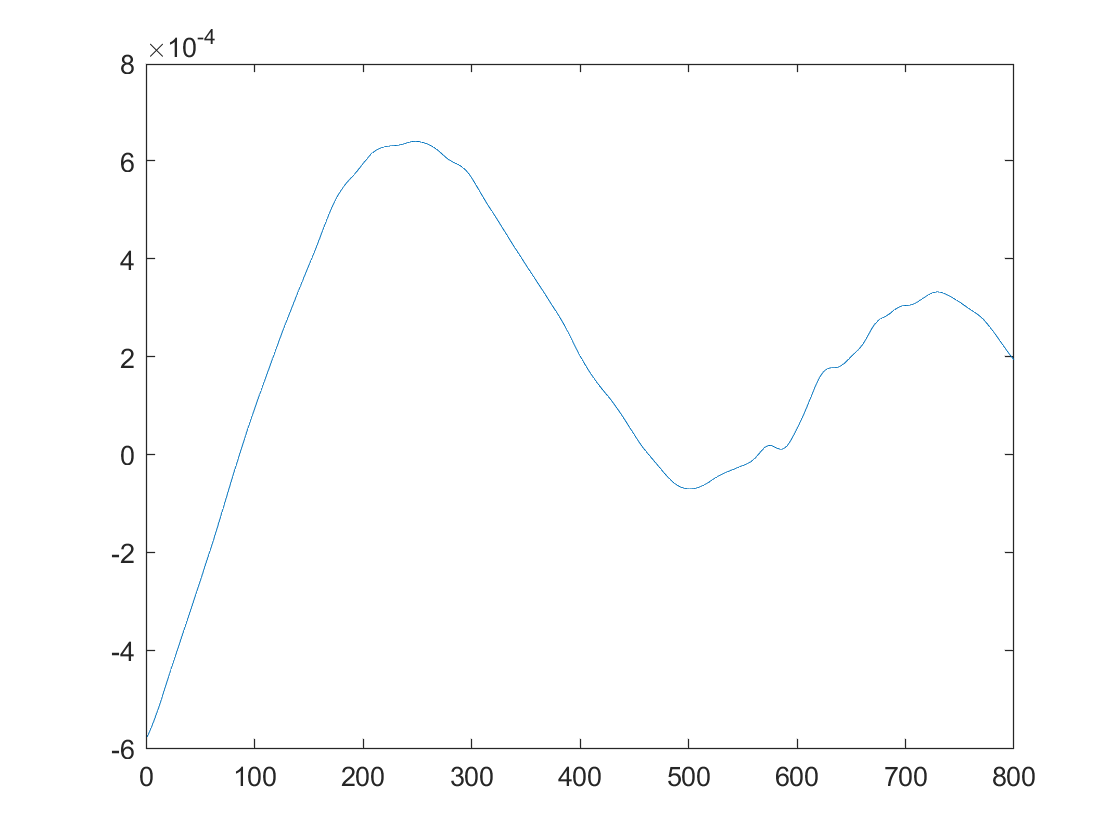

eqa = importdata('..//..//temp//simu86400//eqa_86400.txt'); 
diff2_eqa = diff(diff(eqa, 1, 1), 1, 1);

pc_a = [1.50; 0.00004; 0.00004];
pc_b = [1.50; 0.00004; 0.00004];

t = 0: 1: 86400 - 5;
alt_angle_sin = deg2rad(2 + 1 * sin(2 * pi / 250 * t))';
phase_centre_simu = pc_a(1) + pc_b(1) * cos(alt_angle_sin) - pc_b(3) * sin(alt_angle_sin); diff_simu = diff(phase_centre_simu);
% phase_centre_simu = importdata('../../temp/simu86400/simu_86400.txt');
diff2_simu = diff(phase_centre_simu, 2);
acc_grav = importdata("..//..//temp//acc_grav.txt");
%vel_grac = cumtrapz(acc_grav, 1);
acc_grav_rela = [acc_grav(:, 1) - acc_grav(:, 4), acc_grav(:, 2) - acc_grav(:, 5), acc_grav(:, 3) - acc_grav(:, 6)];
%vel_grav_rela = [vel_grav(:, 1) - vel_grav(:, 4), vel_grav(:, 2) - vel_grav(:, 5), vel_grav(:, 3) - vel_grav(:, 6)];
gnv_a = importdata("..//..//input//normal1/TH04-01_KOE1B_2019-01-01_A_04.asc");
gnv_b = importdata("..//..//input//normal1/TH04-01_KOE1B_2019-01-01_B_04.asc");
gni_a = importdata("..//..//input//normal1/TH04-01_ROI1B_2019-01-01_A_04.asc");
gni_b = importdata("..//..//input//normal1/TH04-01_ROI1B_2019-01-01_B_04.asc");
kbr_x = importdata("..//..//input//normal1/TH04-01_KBR1B_2019-01-01_X_10.asc");
range_acc = kbr_x.data(1: 800, 3);

pos_rela = gnv_a.data(:, 1: 3) - gnv_b.data(:, 1: 3);
pos_rela_i = gni_a.data(:, 1: 3) - gni_b.data(:, 1: 3);
los = pos_rela ./ sqrt(diag(pos_rela * pos_rela'));
los_i = pos_rela_i ./ sqrt(diag(pos_rela_i * pos_rela_i'));
vel_rela = gni_a.data(:, 7: 9) - gni_b.data(:, 7: 9);
los_vec = vel_rela ./ sqrt(diag(pos_rela * pos_rela')) - pos_rela_i .* dot(los_i, vel_rela, 2) ./ diag(pos_rela * pos_rela');

range_acc_grav = zeros(length(los), 1);
for i = 1: length(range_acc_grav)
    range_acc_grav(i) = dot(acc_grav_rela(i, :), los(i, :)) + dot(vel_rela(i, :), los_vec(i, :));
end
range_acc_grav = range_acc_grav(1: 5: length(range_acc_grav));
range_acc_res = range_acc - range_acc_grav - diff2_simu(1: 800);
figure;
plot(range_acc_grav);

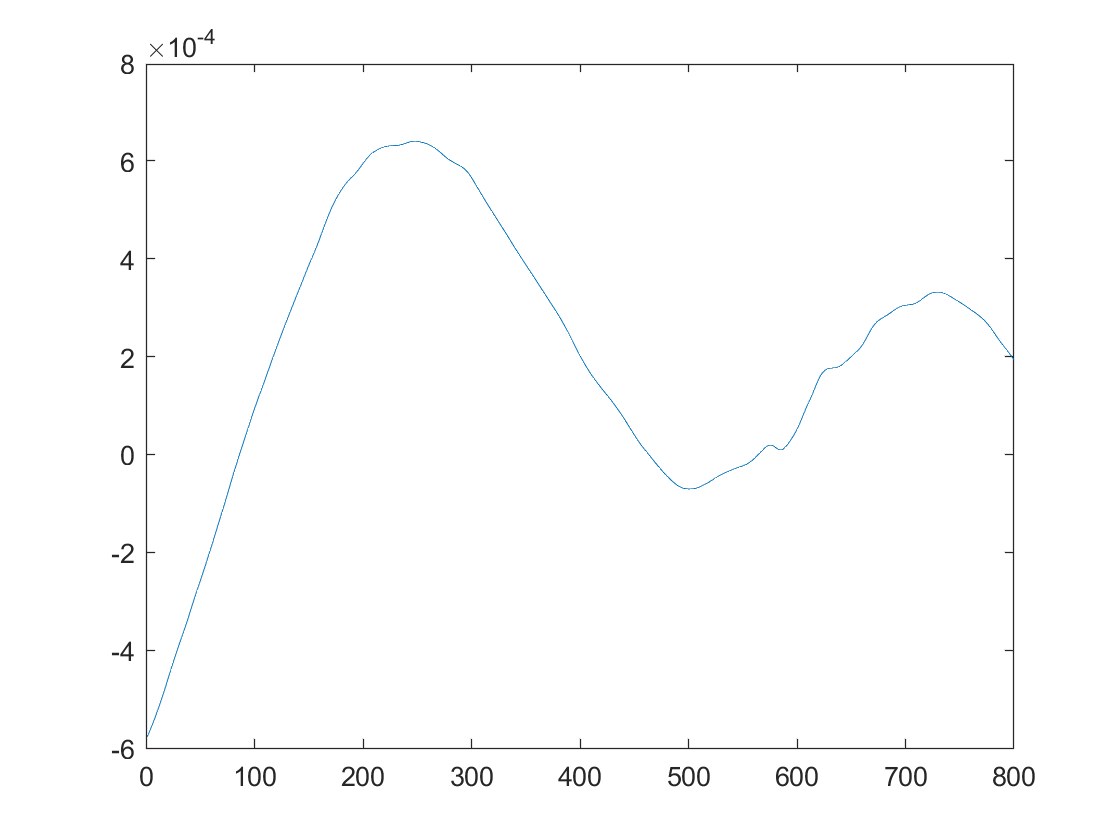

figure;
plot(range_acc);

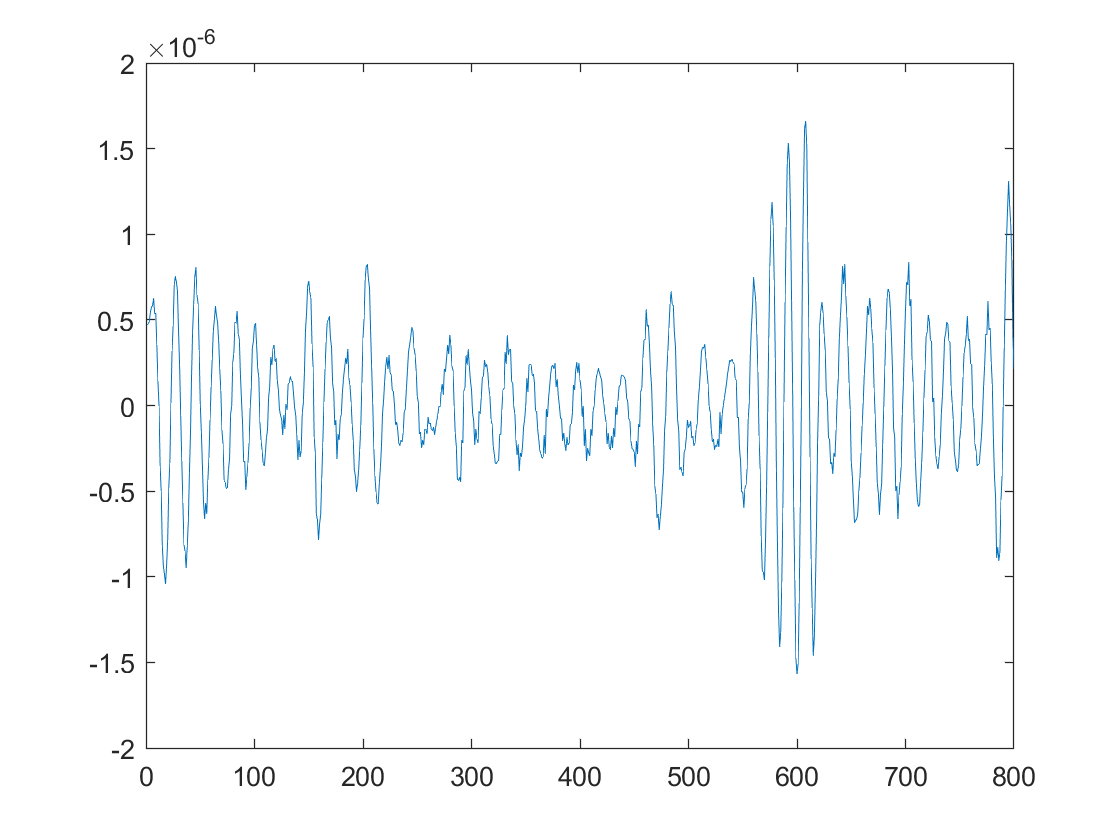

figure;
plot(range_acc - range_acc_grav);

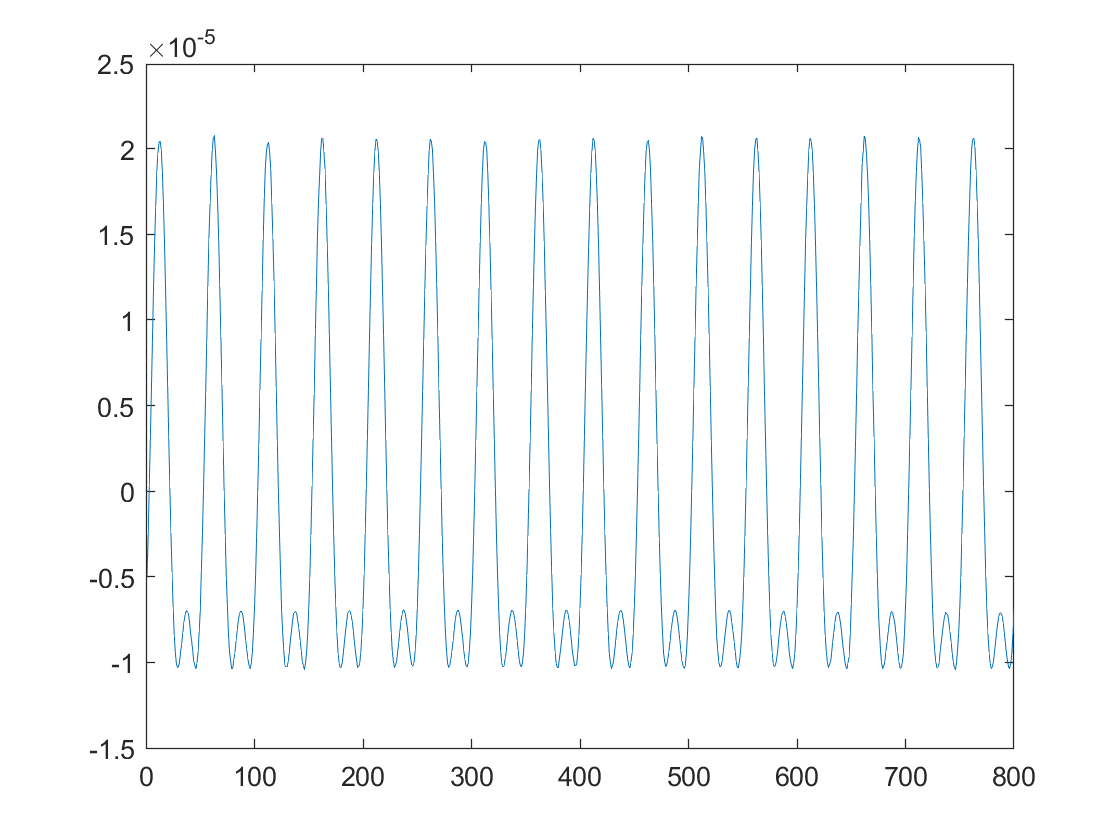

figure;
plot(diff2_eqa(1: 800, 1: 3) * pc_b + diff2_eqa(1: 800, 4: 6) * pc_a)

ccc = solver_spectral(diff2_eqa(1: 450, :), -range_acc_res(1: 450), [1 3], 0.2)

lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.0075。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.0075。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.0075。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.0074。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.0074。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.0074。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.99。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.99。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.99。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 2.7e-11。


ccc =     23.9799821983611e-003
    679.911987657549e-006


bbbb = lsqr(diff2_eqa(1: 600, :), -range_acc_res(1: 600))

lsqr 在解的 迭代 6 处收敛，并且相对残差为 1。


bbbb =     2.21818666211514e-003
    5.35068906189954e-003
    495.500001560788e-006
    2.51619861033242e-006
   -2.26045657112476e-003
   -1.99262652906375e-003


bbbb = [bbbb(1), bbbb(3)];
acos(dot(bbbb, [1.5, 5e-5]) / norm(bbbb) / norm([1.5, 5e-5]))

ans =     219.739264825876e-003
